clf
data = readtable('observations-361592.csv') % import data

data = 691×5 table
    observed_on            created_at             latitude    longitude        scientific_name     
    ___________    ___________________________    ________    _________    ________________________

    2019-10-20     {'2019-10-20 17:06:42 UTC'}     32.773      -117.14     {'Sayornis nigricans'  }
    2020-08-12     {'2020-08-12 20:25:51 UTC'}     32.773      -117.14     {'Spinus psaltria'     }
    2020-08-12     {'2020-08-12 20:25:52 UTC'}     32.773      -117.14     {'Psaltriparus minimus'}
    2020-08-12     {'2020-08-12 20:25:53 UTC'}     32.773      -117.14     {'Thryomanes bewickii' }
    2020-08-12     {'2020-08-12 20:25:53 UTC'}     32.773      -117.14     {'Haemorhous mexicanus'}
    2020-08-14     {'2020-08-14 18:52:36 UTC'}     32.773      -117.14     {'Zenaida macroura'    }
    2020-0

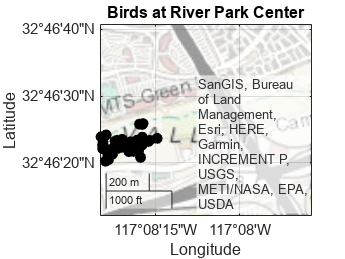

coord = table2array(data(:,3:4)); % create coordinates array (lat, lon)
lat = coord(:,1);
lon = coord(:,2);

lat1 = 32.77; % latitude bound (southbound)
lat2 = 32.778; % latitude bound (northbound)
lon1 = -117.14; % longtitude (westbound)
lon2 = -117.13; % longitude (eastbound)

geolimits([lat1 lat2],[lon1 lon2]) % coordinate points River Park Center
geoplot(lat,lon,"ok",MarkerFaceColor="k") % plot all bird observations
title("Birds at River Park Center")
geobasemap topographic % display map type


spec = string(table2array(data(:,"scientific_name"))); % string array of species
crow = find(spec=='Corvus brachyrhynchos'); % index values of crows in data
coordc = [lat(crow),lon(crow)]; % coordincates crow observations

geolimits([lat1 lat2],[lon1 lon2]) % coordinate points River Park Center

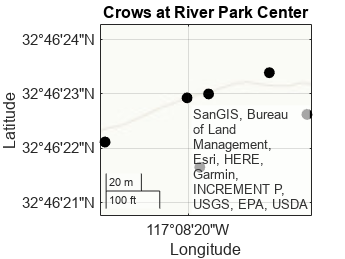

geoplot(lat(crow,:),lon(crow,:),"ok",MarkerFaceColor="k") % plot all crow observations 
title("Crows at River Park Center")
geobasemap topographic % display map type